# CIC data for simulation

## 1. What data is necessary?

### Flows profile generation

The last item of the **Import** menu in the **Ephemeris** ribbon group allow to generate the **Flows profile files** From geometrical data. Inputs and ouput are CIC-CCSDS files

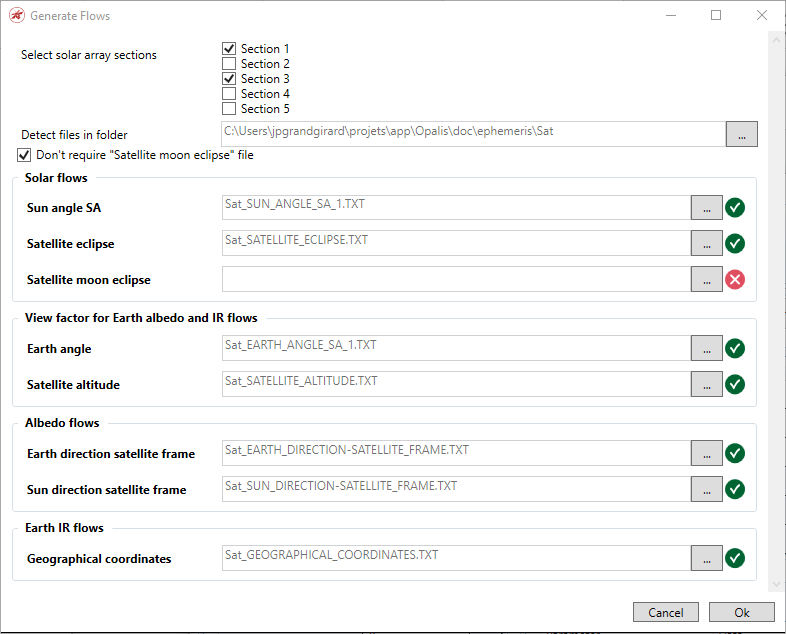

### Files specification

**Sun angle SA (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the sun direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_ANGLE_SA_1.

**Satellite eclipse (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the earth. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE.

**Satellite moon eclipse (optional)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the moon. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE_MOON. This file is not required if the *Don’t require “Satellite moon eclipse” file* control is checked.

**Earth angle (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the earth direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_ANGLE_SA_1.

**Satellite altitude (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the altitude of the satellite in kilometers. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ALTITUDE.

**Earth direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Earth direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_DIRECTION-SATELLITE_FRAME.

**Sun direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Sun direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_DIRECTION-SATELLITE_FRAME.

**Geographical coordinates (required)**

Standard CIC-CCSDS MEM file with 2 real data columns. The data represents the longitude and latitude of the satellite in degrees. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by GEOGRAPHICAL_COORDINATES.

### Power profile file

This file describes the spacecraft power consumption in Watt. This file is used when when **Power consumption mode** is setted to **Profil**.

This file is intended to be a CIC SATELLITE_CONSUMED_POWER standard file but every MEM file with exactly one REAL column can be used.

## 2. Creating the simulink

The simulink file created to generate the data is: ***CICdatapowerfrompropagator.slx***

But first, to initialize it, we need to configure some parameters:

clear
close

%Initialisation of date
date.year=2024;
date.month=9;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
orbit.R_earth=6378e3;
orbit.altitude=300e3;
orbit.a = 6678e3;       %semimajor axis [m]
orbit.e = 0.001;        %eccentricity
orbit.i = 96.7;           %inclination [degrees]
orbit.O = 0;            %Right ascension of the right ascending node [degrees] 
orbit.o = 0;            %Argument of the perigee [degrees]                      
orbit.nu = 0;           %True anomaly [degrees]
%In this case, RAAN=orbit.O is close to the Beta angle.

%time step  
%TimeStep = 10;        %fixed-step size in solver, Default time step=0.25
%TimeStep = 3;        %fixed-step size in solver
TimeStep = 1;        %fixed-step size in solver
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
Torb=Torbit;
N_orbits = 2;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
%t_sim = N_orbits*Torbit;
t_sim = 48 * 60 * 60; %2 days
MODE=2;

%Power Generation
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -Z side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Z side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion

angle_roll = pi/4;  %Rotated angle in roll for MODE 9

### **Loads**

To load the power consumption of the loads:

First, the thruster, the thrust duration is 50 minutes, the heating duration is 16 minutes, it will wait for some time before starting a first cycle, in this case, we set this to 30 minutes. After the thrust has finished, a recharge time can be set. A total waiting time between two cycles would be the sum between the recharge time and the start time. 


$$t_{thrust}=50min=3000s \\
t_{heating}=16min=960s \\
t_{watiting} =t_{recharge}
$$


Also, there is a time before the thrust fires, it is called starting time, but it doesn't affect the calculation.


$$t_{start} = 30min = 1800s $$


There are two duty cycles that are closely related. The thruster duty cycle is the time that the thruster is producing a thrust, this is used for orbit control, orbit propagation, etc.


$$d_{thruster}=\frac{t_{thrust}}{t_{thrust}+t_{heating}+t_{wait}}$$


From the point of view of power consumption, a different duty cycle is used, but this will not be calculated. Only for reference:


$$d_{thruster {_} power}=\frac{t_{thrust}+t_{heating}}{t_{thrust}+t_{heating}+t_{wait}}$$


If the starting time is fixed, then for a desired duty cycle, only the recharge time can be selected.

This can be calculated with:


$$t_{recharge}=\frac{t_{thrust}}{d_{thruster}}-t_{thrust}-t_{heating}$$


Cbat=2.6;           %Cell capacity in [Ah]
Nbs=1;
Nbp=4;
C=Cbat*Nbp*3600;    %Battery Capacity for all parallel arrays [Ampere*sec]
%Power distribution efficiencies
eff_iBat=0.9;       %efficiency from Battery to load
eff_i1=0.9;         %efficiency PDU CH not regulated
eff_i2=0.9;         %efficiency PDU CH 3.3V
%Battery
DOD_0=0.3;          %initial DOD from 0 to 1
%Charge/Discharge logic
I_BD_max= 5.2*Nbp;     %Maximum discharge current [A] approx. 2C rate
I_BC_max= 2.6*Nbp;     %Maximum charge current [A] approx. 1C rate

### Loads

Listed below all the loads

%Thruster required power
Pload1=12;          %Required power Thruster [W]
%t0_Th=30*60;        %Time wait before first use of the Thruster;
t0_Th=110*60;        %Time wait before first use of the Thruster;
t_rech=350*60;        %time waiting between 2 firings, recharging [seconds], 350 minutes
t_heat=10;       %time heating thruster: in [s]
P_heat=3;
T_thrust = 6;      %seconds, total time of thrust (without heating of the thruster)
t_on=T_thrust;
P_idle=0; %0.35W according to datasheet
Duty_cycle=t_on/(t_on+t_rech+t_heat)*100;  %Duty cycle thrust
t_thr=[0,       t0_Th-1, t0_Th,    t0_Th+t_heat,   t0_Th+t_heat+1, t0_Th+t_heat+1+t_on,  t0_Th+t_heat+2+t_on, t0_Th+t_heat+2+t_on+t_rech-t0_Th];
p_thr=[P_idle,  P_idle,  P_heat,   P_heat,         Pload1,         Pload1,               P_idle,              P_idle];

%subsystem loads
P_OBC=0.015;         %Required power OBC [W]
eff_OBC=0.9;         %efficiency CH OBC

P_ADC=0.463;         %power consumption by sensors and eq. at 3.3V
%P_ADC=2.063;         %power consumption by sensors and eq. at 3.3V
eff_ADC1=0.9;        %Efficiency CH ADCS 1 3.3V
% Pload3=4.5;          %Required power ADCS w/o RWA [W]

P_eps = 0.5;         %internal power consumption EPS [W]

%Com subsystem
%t0_tx=Torb/2+600;    %10 minutes after half orbit [s]
t0_tx=0.8*Torb+600;    %10 minutes after 1 orbit [s]
%P_Rx=0.29;          %Required power Com (Rx)[W]
%P_Rx=0.22;           %Required power Com (Rx)[W]
P_Rx=0.341;           %Required power Com (Rx)[W]
%PtxCOM=1.57;        %power if tx every orbit (average)
P_Tx=2.6+P_Rx;       %Peak power UHF [W]
%t_wait_Tx=4*Torb;    %Waiting time before Transmission [s]
t_wait_Tx=3.7*Torb;    %Waiting time before Transmission [s]
p_tx_UHF=[P_Rx   P_Rx        P_Tx   P_Tx       P_Rx          P_Rx];
t_tx_UHF=[0      t0_tx-1     t0_tx  t0_tx+600  t0_tx+601     t0_tx+601+t_wait_Tx];
eff_UHF=0.90;        %efficiency CH COM

P_Rx_S=0.02;           %Required power Com S band (Rx) [W]
P_Tx_S=28.8;           %Peak power Com S band [W]
t0_S=5*3600;           %time before first Tx [s]
t_onS=5*60;            %Tx time in seconds
t_waitS=90*60;         %waiting time before tx [s]
t_endS=24*60*60;       %end time of tx 1 day [s]
l=5;                   %number of thrusts
p_tx_S=P_Rx_S*ones(1,l*4+2);
t_tx_S=zeros(1,length(p_tx_S));
for n=0:l-1
    p_tx_S(3+n*4)=P_Tx_S;
    p_tx_S(4+n*4)=P_Tx_S;
    t_tx_S(2+n*4)=t0_S+(n+1)*(t_waitS)-1;
    t_tx_S(3+n*4)=t0_S+(n+1)*(t_waitS);
    t_tx_S(4+n*4)=t0_S+(n+1)*(t_waitS)+t_onS;
    t_tx_S(5+n*4)=t0_S+(n+1)*(t_waitS)+t_onS+1;
end
t_tx_S(l*4+2)=t_endS;
% p_tx_S=[P_Rx_S   P_Rx_S   P_Tx_S   P_Tx_S        P_Rx_S        P_Rx_S];
% t_tx_S=[0        t0_S-1   t0_S     t0_S+t_onS    t0_S+t_onS+1  t0_S+t_onS+1+t_wait_Tx];
eff_S=0.95;          %efficiency CH COM


P_GPS=0.15;        %Required power GPS [W]
eff_GPS=0.9;       %efficiency CH 

P_heater=3;         %Required power heater [W], 2 heaters\
t0_Fi=10*90*60;     %approx 10 orbits in [seconds]
tON_Fi=90*60;       %Duration of Fipex payload on in [seconds]
tend_Fi=24*60*60;   %end of cycle, 1 day, 1 activation per day
P_idle_Fi=0;
p_Fi=[P_idle_Fi   P_idle_Fi   P_heater   P_heater       P_idle_Fi          P_idle_Fi];
t_Fi=[0           t0_Fi-1     t0_Fi      t0_Fi+tON_Fi  t0_Fi+tON_Fi+1    tend_Fi];

Listed below which loads are active

EN_Thr=1;           %Thruster Enabled=1, disabled=0
EN_OBC=1;           %OBC Enabled=1, disabled=0
EN_ADCS1=1;         %ADCS 3.3V Enabled=1, disabled=0
EN_UHF=1;           %TRx UHF enabled=1
EN_S=1;             %S band TP enabled=1
EN_GPS=1;           %GPS Enabled=1, disabled=0
EN_heat=1;          %Fipex Enabled=1, disabled=0

To open the simulation:

%CICdatapowerfrompropagator

To get the data out from the simulation:

out=sim('CICdatapowerfrompropagator_LoLaSat')

out =   Simulink.SimulationOutput:

            Earth_angle: [1x1 timeseries] 
        Earth_direction: [1x1 timeseries] 
                     LL: [1x1 timeseries] 
                   LOAD: [1x1 timeseries] 
           Sun_angle_SA: [1x1 timeseries] 
          Sun_direction: [1x1 timeseries] 
             TOTAL_LOAD: [1x1 timeseries] 
                   T_JD: [1x1 timeseries] 
                    alt: [1x1 timeseries] 
                eclipse: [1x1 timeseries] 
               eclipse1: [1x1 timeseries] 
                   tout: [172801x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Processing data:

timesec = out.tout;
time=timesec/60;  %to plot in minutes
%DOD = getdatasamples(out.DOD,(1:length(time)));
%Vbat = getdatasamples(out.Vbat,(1:length(time)));
%Ibat = getdatasamples(out.Ibat,(1:length(time)));
%SOC = 100*(1 - DOD);
%Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
%beta = getdatasamples(Power.beta,(1:length(time)));
Ploads = getdatasamples(out.LOAD,(1:length(time)));

The plots show the following:

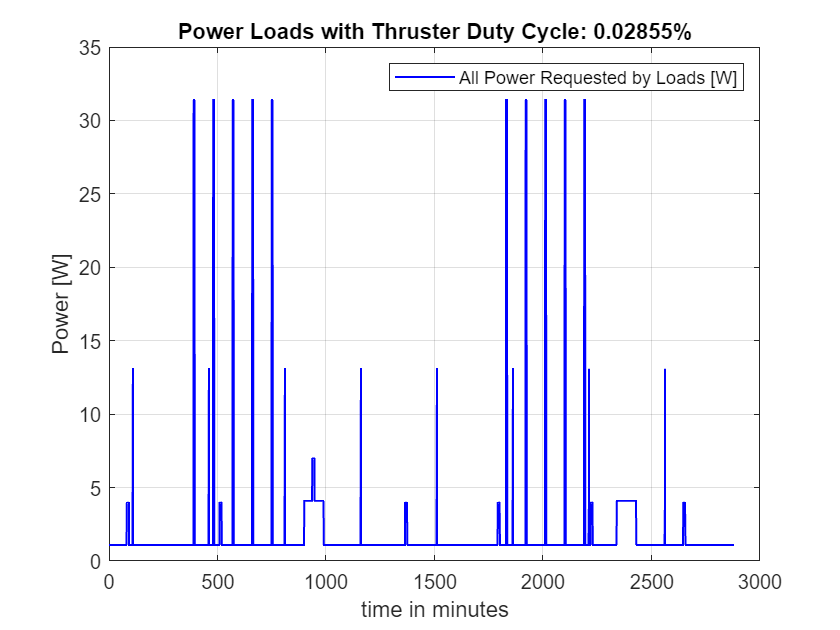

close all
time=timesec/60;  %to plot in minutes
figure()
set(gcf,'color','w');
    subplot(1,1,1)
        plot(time,Ploads,'b','LineWidth',1)
        hold on;
        legend('All Power Requested by Loads [W]')
        if EN_Thr==1
            title(['Power Loads with Thruster Duty Cycle: ',num2str(Duty_cycle),'%'])
        else
            title('Power Loads')
        end
        ylabel('Power [W]')
        xlabel('time in minutes')
        %ylim([0,22])
        grid on

### Converting the data to CIC format

Now we can run the script to convert the data to the CIC format

NOTE: Be sure to be on the folder above the CICData folder where the CIC files will be created.

CIC_writer_EPS_LoLaSat

Opening out file
Writing metadata
Writing Sun angle
Writing eclipse fraction
Writing Power loads
Adding data to metadata file
Done!


and finally, copy these files to the OPALIS directory

NOTE: Be sure to be on the folder above the CICData folder where the CIC files were created.

The destination folder can be changed to your own folder.

% copyfile("./CICData/data_earth_angle.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_earth_dir.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_eclipse.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_geo_latlon.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sat_alt.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sun_angle.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sun_dir.txt","C:\CNES\OPALIS\IonSat")
%copyfile("./CICData/data_p_loads.txt","C:\CNES\OPALIS\IonSat")
%copyfile("./CICData/data_p_loads.txt","C:\Users\lricc\Documents\ZfT\sims Matlab")

## 3. Simulation in OPALIS

This is not done in Matlab

In Opalis the following configuration was chosen: